# Split division

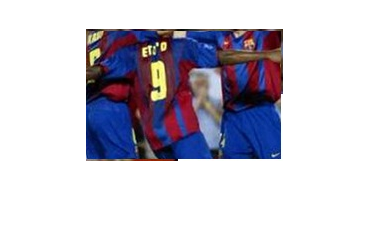

clear
format long G
%imPrueba = imread('..\acmilan\01.jpg');
imPrueba = imread('16.jpg');
imshow(imPrueba)

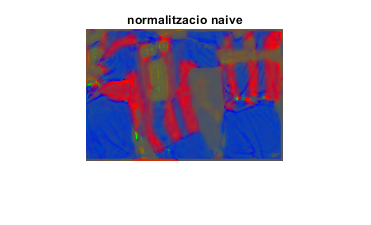

rTest = imPrueba(:,:,1);
gTest = imPrueba(:,:,2);
bTest = imPrueba(:,:,3);
ITest = double(rTest)+double(gTest)+double(bTest);
rTestn = uint8((double(rTest)./ITest)*255);
gTestn = uint8((double(gTest)./ITest)*255);
bTestn = uint8((double(bTest)./ITest)*255);
rgbTestNormalizada = cat(3,rTestn,gTestn,bTestn);
%rgbTestNormalizada = cat(3,rTestn,zeros(size(rTestn)),bTestn);
imshow(rgbTestNormalizada), title('normalitzacio naive');

%%Normalizacion
%rHistEq = histeq(rTestn);
%bHistEq = histeq(bTestn);
%gHistEq = histeq(gTestn);
%rgbTestNormalizada = cat(3,rHistEq,gHistEq,bHistEq);
%imshow(rgbTestNormalizada), title('Histograma Equalizado')

n = 1

n =      1


[h, w, d] = size(rgbTestNormalizada)

h =    132


w =    197


d =      3


hAux = fix(h/n)

hAux =    132


wAux = fix(w/n)

wAux =    197


hAux2 = h-(hAux*(n-1))

hAux2 =    132


wAux2 = w-(wAux*(n-1))

wAux2 =    197


a1 = ones(1,n);
a2 = ones(1,n);
for i = 1:(n-1)
    a1(i) = hAux;
    a2(i) = wAux;
end
a1(n) = hAux2;
a2(n) = wAux2;
mat16 = mat2cell(rgbTestNormalizada,a1,a2, [d]);
aux = 0:0.01:1;
%imshow(mat16{1,1});

chiTotal = 2

chiTotal =      2


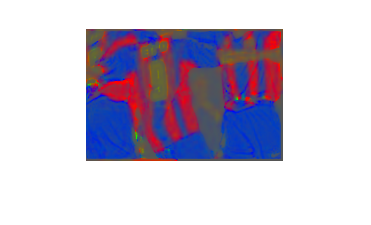

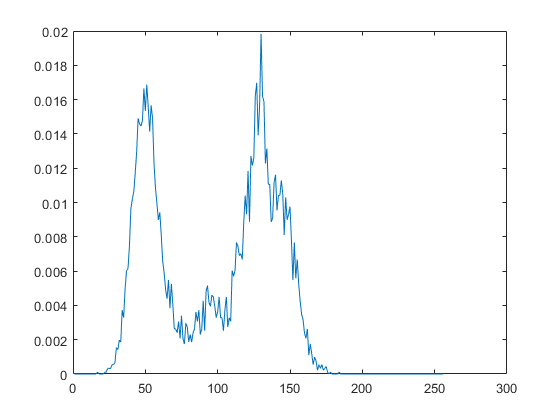

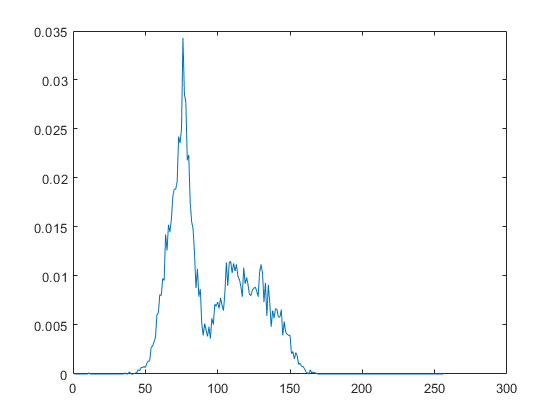

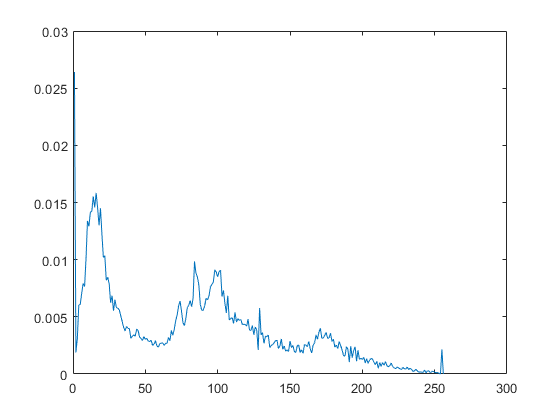

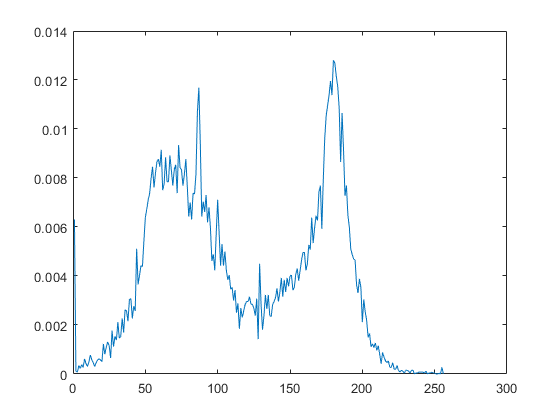

total =           1.46263471812218


for i = 1:n
    for j = 1:n
        subImagen = mat16{i,j};
        figure
        imshow(subImagen);
        rTest = subImagen(:,:,1);
        gTest = subImagen(:,:,2);
        bTest = subImagen(:,:,3);
        %rHistEq = histeq(rTest);
        %bHistEq = histeq(gTest);
        %gHistEq = histeq(bTest);
        %bar(rHistEq)
        %bar(bHistEq)
        %bar(gHistEq)
        %rTest = uint8(rTest * 256);
        %gTest = uint8(gTest * 256);
        %bTest = uint8(bTest * 256);
        rTestHisto = getHisto(rTest);
        gTestHisto = getHisto(gTest);
        bTestHisto = getHisto(bTest);
        %Empezamos comprobacion imagen
        for k = 41:41
            if k < 10
                im = imread(strcat( '..\fuentes\' ,'0', int2str(k) ,'.jpg'));
            else
                im = imread(strcat('..\fuentes\' ,int2str(k) ,'.jpg'));
            end
            %imshow(im)
            r = im(:,:,1);
            g = im(:,:,2);
            b = im(:,:,3);
            I = double(r)+double(g)+double(b);
            rn = double(r)./I;
            gn = double(g)./I;
            bn = double(b)./I;
            rgbNormalizada = cat(3,rn,gn,bn);
            r = uint8(rn * 255);
            g = uint8(gn * 255);
            b = uint8(bn * 255);
            rHisto = getHisto(r);
            gHisto = getHisto(g);
            bHisto = getHisto(b);
            
            rHisto = rHisto/sum(rHisto);
            gHisto = gHisto/sum(gHisto);
            bHisto = bHisto/sum(bHisto);
            rTestHisto = rTestHisto/sum(rTestHisto);
            gTestHisto = gTestHisto/sum(gTestHisto);
            bTestHisto = bTestHisto/sum(bTestHisto);
            figure
            plot(rHisto)
            figure
            plot(bHisto)
            figure
            plot(rTestHisto)
            figure
            plot(bTestHisto)
            chiR(i,j) = distChi(rHisto,rTestHisto);
            chiG(i,j) = distChi(gHisto,gTestHisto);
            chiB(i,j) = distChi(bHisto,bTestHisto);
            total = chiR(i,j) +  chiB(i,j)
            if (total < chiTotal)
                i_total = i;
                j_total = j;
                chiTotal = total;
            end
        end
    end
end

i_total

i_total =      1


j_total

j_total =      1


chiR(i_total,j_total) 

ans =          0.788347275269605


chiG(i_total,j_total) 

ans =          0.379121632766236


chiB(i_total,j_total) 

ans =          0.674287442852577


subImagen = mat16{i_total,j_total};
imshow(subImagen)

# Split division with steps

clear
format long G
%imPrueba = imread('..\acmilan\01.jpg');
imPrueba = imread('08.jpg');
imshow(imPrueba)
rTest = imPrueba(:,:,1);
gTest = imPrueba(:,:,2);
bTest = imPrueba(:,:,3);
ITest = double(rTest)+double(gTest)+double(bTest);
rTestn = uint8((double(rTest)./ITest)*255);
gTestn = uint8((double(gTest)./ITest)*255);
bTestn = uint8((double(bTest)./ITest)*255);
rgbTestNormalizada = cat(3,rTestn,gTestn,bTestn);
imshow(rgbTestNormalizada), title('normalitzacio naive');


chiTotal = 2^32;
[h, w, d] = size(rgbTestNormalizada)
pasos_y = 40;
pasos_x = 40;
height_of_the_windows = 100;
width_of_the_windows = 100;

for i = 1:pasos_y:(w-pasos_y)
    for j = 1:pasos_x:(h-pasos_x)
        height_of_the_windows_aux = height_of_the_windows;
        width_of_the_windows_aux = width_of_the_windows;
        if (i+height_of_the_windows> h)
            height_of_the_windows_aux = h-i;
        end
        if (j+width_of_the_windows> w)
            width_of_the_windows_aux = w-j;
        end
        
        subImagen = rgbTestNormalizada(i:(i+height_of_the_windows_aux-1),j:(j+width_of_the_windows_aux-1),:);
        figure
        %imshow(subImagen)
        rTest = subImagen(:,:,1);
        gTest = subImagen(:,:,2);
        bTest = subImagen(:,:,3);
        rTestHisto = getHisto(rTest);
        gTestHisto = getHisto(gTest);
        bTestHisto = getHisto(bTest);
        
        %Empezamos comprobacion imagen
        for k = 2:8
            if k < 10
                im = imread(strcat( '..\fuentes\' ,'0', int2str(k) ,'.jpg'));
            else
                im = imread(strcat('..\fuentes\' ,int2str(k) ,'.jpg'));
            end
            %imshow(im)
            r = im(:,:,1);
            g = im(:,:,2);
            b = im(:,:,3);
            I = double(r)+double(g)+double(b);
            rn = double(r)./I;
            gn = double(g)./I;
            bn = double(b)./I;
            rgbNormalizada = cat(3,rn,gn,bn);
            %imshow(rgbNormalizada), title('normalitzacio naive')
            rHisto = getHisto(uint8(rn*255));
            gHisto = getHisto(uint8(gn*255));
            bHisto = getHisto(uint8(bn*255));
            
            rHisto = rHisto/sum(rHisto);
            gHisto = gHisto/sum(gHisto);
            bHisto = bHisto/sum(bHisto);
            rTestHisto = rTestHisto/sum(rTestHisto);
            gTestHisto = gTestHisto/sum(gTestHisto);
            bTestHisto = bTestHisto/sum(bTestHisto);
            
            chiR = distChi(rHisto,rTestHisto);
            chiG = distChi(gHisto,gTestHisto);
            chiB = distChi(bHisto,bTestHisto);
            total = chiR + chiB;
            if (total < chiTotal)
                i_total = i;
                j_total = j;
                i_total2 = (i+height_of_the_windows_aux-1);
                j_total2 = (j+width_of_the_windows_aux-1);
                chiTotal = total;
            end
        end
    end
end
i_total
j_total
%chiR(i_total,j_total) 
%chiG(i_total,j_total) 
%chiB(i_total,j_total)
chiTotal
imshow(imPrueba(i_total:i_total2,j_total:j_total2,:))

function d = distChi(l1,l2)
    aux = (l1 == l2);
    l1 = l1 + double(aux);
    l2 = l2 + double(aux);
    d = sum(((l1-l2).^2)./(l1+l2));
end

function h = getHisto(im)
    h = zeros(1,256);
    [files cols] = size(im);
    for f=1:files
        for c=1:cols
            h(im(f,c)+1) = h(im(f,c)+1)+1;
        end
    end
end